%loading example file
dirpath = "/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/extracted_sleep_epochs_v2/"

dirpath = "/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/extracted_sleep_epochs_v2/"

subj = "Spat52"

subj = "Spat52"

filename = "Spat52_R_POD1.mat"

filename = "Spat52_R_POD1.mat"

fpath = fullfile(dirpath, subj, filename)

fpath = "/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/extracted_sleep_epochs_v2/Spat52/Spat52_R_POD1.mat"

spat52_R = load(fpath)

spat52_R = struct with fields:
     bip_montage_label: ["LAC1 - LAC2"    "LAC2 - LAC3"    "LAC3 - LAC4"    "LI13 - LI14"    "LI14 - LI15"    "RTF1 - RTF2"    "RTF2 - RTF3"    "RTF3 - RTF4"    "LTF1 - LTF2"    "LTF2 - LTF3"    "LTF3 - LTF4"    "LTF4 - LTF5"    …    ] (1×100 string)
    bip_montage_region: ["ctx-lh-caudalanteriorcingulate"    "ctx-lh-caudalanteriorcingulate"    "ctx-lh-caudalanteriorcingulate"    "ctx-lh-caudalmiddlefrontal"    "ctx-lh-caudalmiddlefrontal"    "ctx-lh-fusiform"    …    ] (1×100 string)
             filt_data: [100×153600 double]
         sampling_freq: 512


fs = spat52_R.sampling_freq

fs = 512

n_samps = size(spat52_R.filt_data,2)

n_samps = 153600

time = (1:n_samps)/fs

time =     0.0020    0.0039    0.0059    0.0078    0.0098    0.0117    0.0137    0.0156    0.0176    0.0195    0.0215    0.0234    0.0254    0.0273    0.0293    0.0312    0.0332    0.0352    0.0371    0.0391    0.0410    0.0430    0.0449    0.0469    0.0488    0.0508    0.0527    0.0547    0.0566    0.0586    0.0605    0.0625    0.0645    0.0664    0.0684    0.0703    0.0723    0.0742    0.0762    0.0781    0.0801    0.0820    0.0840    0.0859    0.0879    0.0898    0.0918    0.0938    0.0957    0.0977


tiles = tiledlayout(4,1)

tiles =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


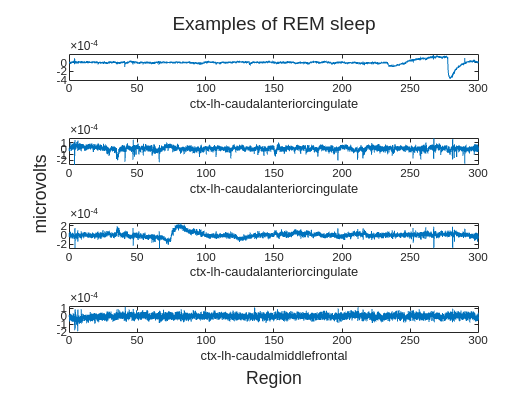

for i=1:4
    nexttile
    plot(time, spat52_R.filt_data(i,:))
    xlabel(spat52_R.bip_montage_region(i))
end
title(tiles,"Examples of REM sleep")%xlabel("Time (s)")
xlabel(tiles, "Region")
ylabel(tiles,"microvolts")

% Score a night of sleep using the SleepSeeg algorithm
%Algorithm requires a whole night of sleep for some reason
raw_sleep_dir = "/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/"

raw_sleep_dir = "/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/"

% get all the files for a night of sleep
files = dir(fullfile(raw_sleep_dir, subj));
filt_inds = contains({files.name}, "filt.edf");
sleep_edfs = files(filt_inds);

sleep_seeg_fpath_cell = {};
for i=1:numel(sleep_edfs)
sleep_seeg_fpath_cell{i} = char(fullfile(raw_sleep_dir, subj, sleep_edfs(i).name))
end

sleep_seeg_fpath_cell = 1×1 cell array
    {'/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/Spat52/Spat52_Night0-0_03012022_filt.edf'}


sleep_seeg_fpath_cell = 1×2 cell array
    {'/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/Spat52/Spat52_Night0-0_03012022_filt.edf'}    {'/mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/Spat52/Spat52_Night1-0_03022022_filt.edf'}


[Summary,SleepStage]=SleepSEEG(sleep_seeg_fpath_cell{1}, subj);

File: /mnt/ernie_main/000_Data/SEEG/SEEG_Sleep_Staging/data/nights_of_sleep/Spat52/Spat52_Night0-0_03012022_filt.edf
959 epochs
Computing features...
Processing:  000%  |                                      | 0/959it [00:00:00<Inf:NaN:NaN, Inf it/s]


From what I'm seeing the sleep stage algorithm sorts through a whole night of data and finds the border between all sleep stages. What I like about this algorithm is that it takes a long chunk of recordings and finds where the sleep stages start and end. Whereas other algorithms seems to require you to brebatch all data into 30s chunks. But this presents the obvious issue to the user who doesn't know when a sleep stage starts and stops, thus chunking data may create recordings with multiple stages per snippet. This begs the question **how does this algorithm determine sleep stage length? Furthermore, how does this algorithm work.**

**Questions to answer about sleep staging algorithm:**

- **What model architecture are we using? SVM? NN? Clustering? Other? And what limitations does this impose? NN's can learn highly non-linear relationships but at the cost of interpretability. **

- **What features are we using to classify?**

- **How are chunks reported? Does this just take care of batching for us and have the same limitation of assumptions?**

**Directed Connectivity across sleep stages**

## Directed Connectivity Across Sleep Stages

**PDC from Precalc**


% for Spat52 load W, N2, N3, and R sleep stages
% get in, out, net connectivity for all sleep stages
% may need to rerun code yourself


**Manually Reconstructing PDC**

%Tst

%use field trip and summary stuff from standard code